# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Arthur Dimitri Brito Oliveira

## Relatório de Atividade 1

## Sumário

- Introdução

- O problema Arquétipo - Modelos ARX e o Método de Mínimos Quadrados

- Desenvolvimento

-     Modelo I

-     Modelo II

- Experimentos

- Referências 

## Introdução

Inferir modelos a partir de observações e estudar suas propriedades tem grande relação com o que é o método científico. A identificação de sistemas lida com o desafio de construir modelos matemáticos de sistemas dinâmicos baseado nos dados coletados. Assim, ao interagir com o sistema, é necessário assumir uma relação entre os sinais observados, isto é, possuir um modelo do sistema. Tais modelos variam no que diz respeito aos graus de variação do formalismo matemático. 

Os sistemas reais diferem dos nossos modelos matemáticos. Pode-se comparar determinados aspectos do sistema físico com sua descrição matemática, mas é impossível estabelecer uma conexão exata entre eles. Sendo assim, a aceitação de um modelo deve ser guiada pela sua usabilidade mais do que pela sua exatidão. Modelos ARX podem ser utilizados nesse contexto para estimação de parâmetros de sistemas reais. 

## O problema Arquétipo - Modelos ARX e o Método de Mínimos Quadrados

Um sistema pode ser denotado por uma equação de diferença linear entre a saída $y(t)$ e a entrada $u(t)$:


$$y(t) + a_1y(t-1) + \: ... \: +a_n(t-n) = b_1u(t-1) + \:...\: +b_mu(t-m)$$


Ou seja, dada as observações passadas, é possível determinar o próximo valor de saída. Assim: 


$$y(t) = -a_1y(t-1) + ... + -a_n(t-n)+b_1u(t-1)+...+b_mu(t-m)$$


Em uma notação mais compacta, a saída pode ser expressa como:


$$y(t) = \varphi^T(t)\theta = \left[\matrix{-y(t-1) \:...\:-y(t-n) \: u(t-1) \: ... \:u
(t-m)}\right ] \left[\matrix{a_1 \cr ... \cr a_n \cr b_1 \cr ... \cr b_m}\right]$$


Supondo que não se sabe o valor dos parâmetros $\theta$  e que em um intervalo $1\leq t \leq N$ conhece-se os valores da entrada e da saída por meio do vetor de dados $Z^N=[u(1),y(1) ... \: ...u(N),y(N)]$, pode-se utilizar a formulação do problema de mínimos quadrados para determinar o valor ótimo para os parâmtros $\hat \theta$. Assim,


$$v_N(\theta,Z^N) = \frac{1}{N}\sum_{t=1}^{N}(y(t)-\hat y(t|\theta))^2 = \frac{1}{N}\sum_{t=1}^{N}(y(t)-\varphi^T\theta)}^2$$



$$min_\theta V_N(\theta,Z^N)$$


Ao derivar, igualar a zero e isolar $\theta$, encontra-se que a aproximação dos parâmetros pode ser dada por:


$$\hat \theta = \left [\sum_{t=1}^{N}\varphi(t)\varphi^T(t)\right]^{-1}\sum_ {t=1}^{N} \varphi(t)y(t)$$


O vetor $\varphi$ é composto pelos regressores, e este termo faz alusão ao fato de que tenta-se calcular a saída com base nos dados prévios do sistema. Agora digamos que os dados obtidos a partir de medições sejam contaminados por um ruído $e(t)$ com variância $\lambda$. Analogamente, a saída pode ser reescrita como:


$$y(t) = \varphi^T(t)\theta_0 + e(t)$$


Substituindo na expressão de aproximação de $\hat \theta$, tem-se:


$$\hat\theta_N = \sum_{t=1}^{N}\varphi(t)\varphi^T(t)\left[\sum_ {t=1}^{N}\varphi(t)\varphi^T(t)\theta_0 + \sum_{t=1}^{N}\varphi(t)e(t)\right] = R(N)^{-1} \left[\sum_ {t=1}^{N}\varphi(t)\varphi^T(t)\theta_0 + \sum_{t=1}^{N}\varphi(t)e(t)\right] $$


Sendo assim, o erro na estimação dos parâmetros do vetor $\hat \theta_N$ pode ser expresso por:


$$\tilde \theta_N = \hat \theta-\theta_0 = R(N)^{-1}\sum_{t=1}^{N}\varphi(t)e(t) $$


## Desenvolvimento

Dados dois sistemas na forma:


$$y_1 = \frac{q^{-1}}{1-0.8q^{-1} }u + \frac{q^{-1} }{1-0.8q^{-1}}e$$



$$y_2 = \frac{q^{-1}}{1-0.8q^{-1} }u + e$$


Onde $e $~$N(0,1) $ e $u$~$N(0,1) $. 

Reescrevendo, tem-se que a primeiro sistema pode ser escrito como:


$$y(t)(1-0.8q^{-1})=(u(t) + e(t))q^{-1} $$



$$y(t) = u(t-1) -0.8*-y(t-1) + e(t-1)$$


O segundo sistema pode ser expresso por:


$$y(t)(1-0.8q^{-1}) = uq^{-1} + e$$



$$y(t) = u(t-1) -0.8*-y(t-1) + e(t) - e(t-1) $$


### Modelo I

Analisando o primeiro modelo, da esperança do erro de estimativa dos parâmetros é dada por:


$$E\tilde \theta_N = E\left[R(N)^{-1} \sum_{t=1}^{N}\varphi(t)e(t)\right] = R(N)^{-1} \sum_{t=1}^{N}\varphi(t)Ee(t) = 0$$


Como o erro $e(t)$ tem média nula, a estimativa independe do erro. Além disso, se a matriz de covariância da entrada $\bar R$ for não-singular, a matriz de covariância da estimativa dos parâmetros é dada por: 


$$P_N = \frac{\lambda}{N}R^{-1} $$


Isso significa que a aproximação dos parâmetros tende a melhorar com o tempo quando o erro é do tipo gaussiano. 

### Modelo II

No caso do modelo 2, a covariância da matriz de erro de estimação dos parâmetros é dada por:


$$\tilde \theta = \hat \theta - \hat \theta_0 = P(t)\sum_{t=1}^{N}\varphi(t)\left[e(t)-e(t-1)\right]$$



$$P = E(\tilde\theta \tilde \theta^T) = E\left[P(t)\sum_{t,s=1}^{N}\varphi(t)[e(t)+e(t-1)][e(s)+e(s-1)]\varphi(s)^TP(s)\right]$$



$$P = P(t)\sum_{t,s=1}^{N}\varphi(t)\varphi(t)^TP(s)E \left \{ [e(t)+e(t-1)][e(s)+e(s-1)] \right \}$$



$$P = P(t)\sum_{t,s=1}^{N}\varphi(t)\varphi(t)^TP(s)  E[e(t)e(s) + e(t)e(s-1) + e(t-1)e(s) + e(t-1)e(s-1)] $$


Sabendo que $E(XY) = cov(X,Y) + E(X)E(Y)$, em termos dos erros tem-se:


$$E[e(t)e(s)] = E(e(t-1)e(s-1)] =\sigma^2 \delta(0)$$


Para os outros termos:


$$E[e(t-1)e(s)] = Cov[e(t-1)e(s)]=1$$



$$E[e(t)e(s-1)] = Cov[e(t)e(s-1)]=1$$


Havendo $N$ amostras do sinal, isso equivale a $N-1$ impulsos de magnitude $\sigma^2 $. Assim, tem-se que:


$$R = P(t)\sum_{t,s=1}^{N}\varphi(t)\varphi(t)^TP(s)\left(2\sigma^2 + 2\sigma^2(N-1)] = P(t)2\sigma^2[1+(N-1)]\sum_{t,s=1}^{N}\varphi(t)\varphi(s)^TP(s)=P(t)2\sigma^2N$$


A covariância de um sinal $z(t) = e(t)+e(t-1)$ é expressa por: 


$$Cov[z(t),z(t-j)] = Cov[e(t),e(t-j)] + Cov[(e(t-1),e(t-1-j)] + Cov[e(t-1),e(t-j)] + Cov[e(t),e(t-1-j)] $$


Para $j \neq 0$, a expressão acima se torna:


$$Cov[z(t),z(t-1)] = Cov[e(t-1),e(t-j)] + Cov[e(t),e(t-1-j)]$$


Sendo $z(t)$ um ruído do tipo gaussiano, a covariância desse sinal deveria ser nula para qualquer valor de $j$ diferente de zero. Para $j=1$, a expressão equivale a:


$$Cov[z(t),z(t-1)] = Cov[e(t-1),e(t-1)] + Cov[e(t),e(t)] = 2\sigma^2 $$


Sendo $\sigma$ a variância do erro $e(t)$. Esse resultado aponta que o sinal $z(t) $não é um ruído do tipo gaussiano. 

## Experimentos

Simulando os sistemas previamente mencionados no ambiente do Matlab, obteve-se os sinais ruidosos de saída que podem ser visualizados na Figura 1.

main

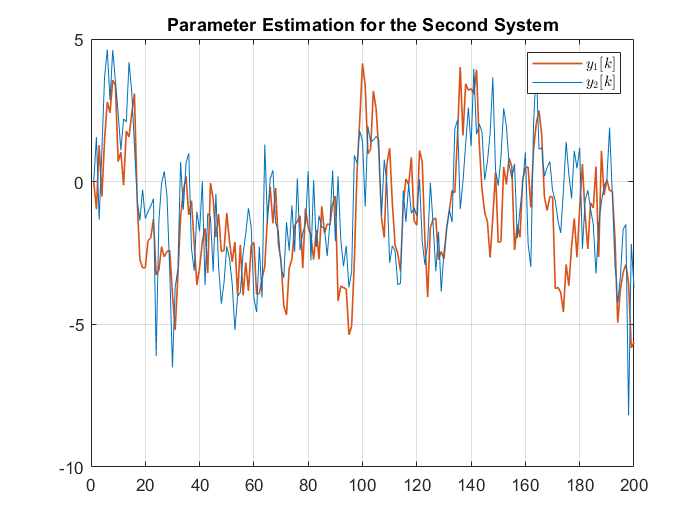

noises_plot

**Figura 1: **Sinais de saída $y_1(t)$ e $y_2(t)$ gerados. 

A estimativa dos parâmetros foi obtida utilizando o método de mínimos quadrados na formulação descrita neste documento. O sistema com saída descrito por: 


$$y(t) = u(t-1) -0.8*-y(t-1) + e(t-1)$$


Como previamente demonstrado, um erro de medição gaussiano não influencia na estimação dos parâmetros. Dessa forma, como esperado, a estimação do vetor de parâmetros tende a melhorar com o tempo. O resultado pode ser observado na Figura 2 referente ao sistema 1. Os parâmetros $â $ e $\hat b$ são estimados corretamente, mesmo com a presença do erro $e(t-1)$. Este resultado já era apontado pela demonstração detalhada na seção de Desenvolvimento. 

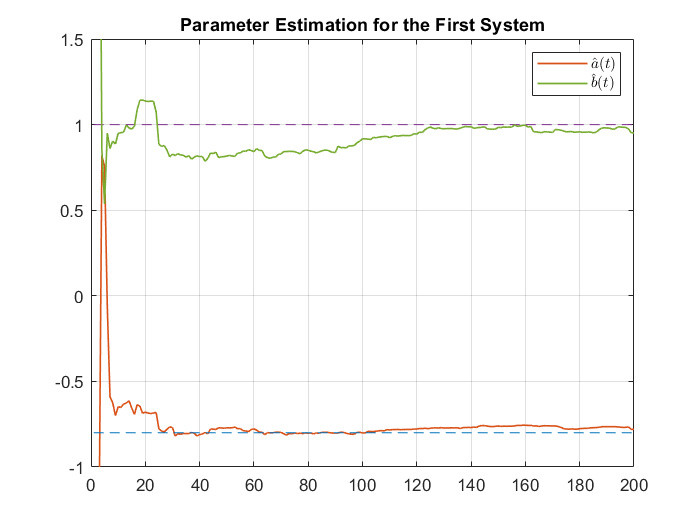

estimatives_plot

**Figura 2: **Estimação dos parâmetros $\hat a$ e $\hat b$ para o sistema 1. 

Com relação ao sistema II, como o sinal ruídoso é do tipo $z(t) = e(t)-e(t-1)$, ele se configura como um ruído não gaussiano. Sendo assim, as demonstrações apontam que o ruído compromete a estimativa, e isto pode ser confirmado ao visualizar a Figura 3. O método de mínimos quadrados não é capaz de prover uma estimativa satisfatória dos parâmetros do sistema. 

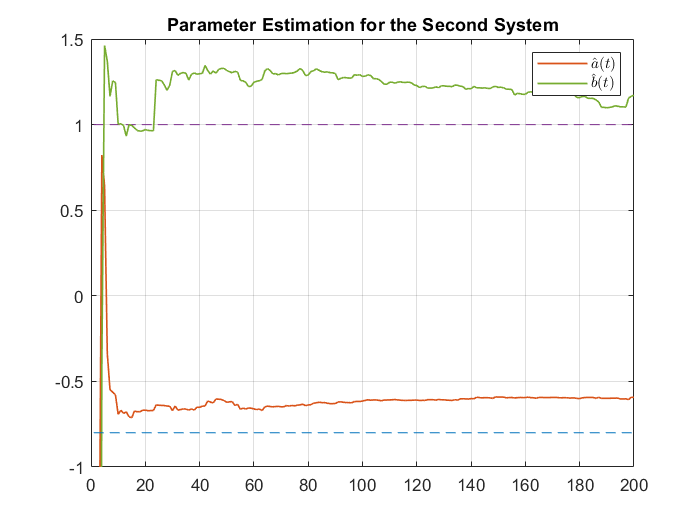

estimatives_plot_2

**Figura 3: **Estimação dos parâmetros $\hat a$ e $\hat b$ para o sistema 2. 

## Referências

[1]   L. LJUNG.** System Identification: Theory for the User **Courier Corporation, 2008. ISBN 0486462781.